# Legge di moto servomotori

Questo script simula fedelmente come la legge di moto viene calcolata sul microcontrollore.

clear all
close all
clf
target_angle = 70; %angolo di target da raggiungere
previous_angle = 30;
smoothing = 0.05; %parametro che regola quanto è morbida e quindi lenta la curva
resolution = 0.3; %Risoluzione angolare del servo. (0.3 gradi)
i = 1;
q = [30];
time = 5; %secondi, tempo di movimentazione

Prima Il programma esegue una simulazione della movimentazione e calcola quante iterazioni sono necessarie per la movimentazione.

while(target_angle-previous_angle >= resolution )
    previous_angle = smoothing*target_angle + (1-smoothing)*previous_angle;
    i = i+1;
end

Noto il numero di iterazioni è possibile calcolare il passo temporale tra passo e l'altro

timestamp = linspace(0,time,i);
target_angle = 70; %angolo di target da raggiungere
previous_angle = 30;
while(target_angle-previous_angle >= resolution )
    previous_angle = smoothing*target_angle + (1-smoothing)*previous_angle;
    q = [q previous_angle]; %Vettore che contiene la posizione del motore
end

In questo modo si ottiene una correlazione tra tempo di movimentazione e movimentazione.

Questa tecnica risulta vantaggiosa nel momento in cui si controllano più motori che devono compiere movimentazione diverse contemporaneamente. Si esegue lo stesso calcolo per ogni motore e si calcola il passo temporale per ogni motore in modo che tutti i motori terminino il movimento assieme.

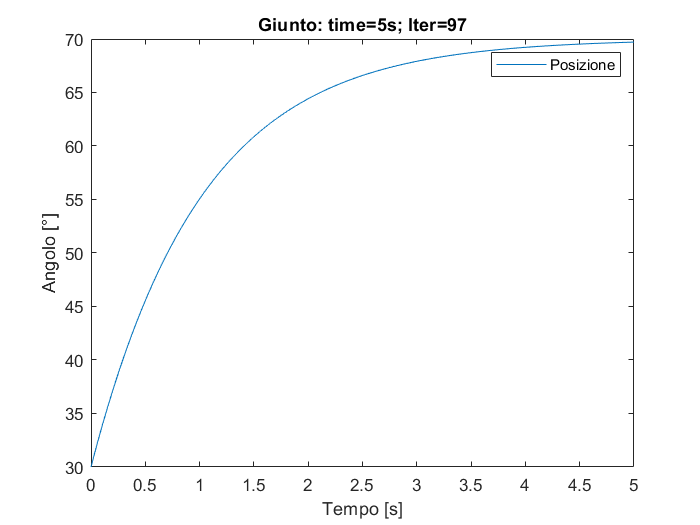

plot(timestamp,q);
title("Giunto: time=" + num2str(time) + "s; Iter="+num2str(i))
legend("Posizione")
xlabel("Tempo [s]")
ylabel("Angolo [°]")

# Motori multipli

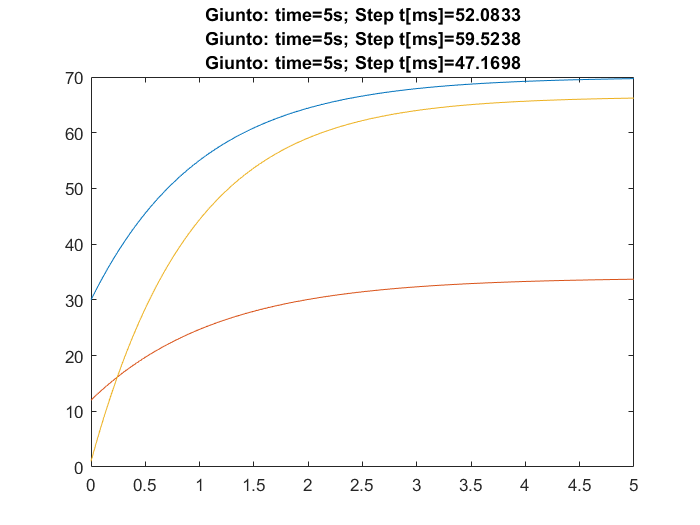

clear all
close all
clf

target_angle = [70;34;66.5]; %angolo di target da raggiungere
previous_angle = [30;12;1];
smoothing = 0.05; %parametro che regola quanto è morbida e quindi lenta la curva
resolution = 0.3; %Risoluzione angolare del servo. (0.3 gradi)
i = [1;1;1];
q = [previous_angle];

time = 5; %secondi, tempo di movimentazione
min_step_time = 0.01; %10ms

for n = 1:size(target_angle)
    while(target_angle(n)-previous_angle(n) >= resolution )
        previous_angle(n) = smoothing*target_angle(n) + (1-smoothing)*previous_angle(n);
        i(n) = i(n)+1;
    end
end
%Calcolo dello step temporale per ogni motore
min_actuation_time = max(i)*min_step_time;
actuation_time = max([time;min_actuation_time]);
timestamp1 = linspace(0,actuation_time,i(1));
timestamp2 = linspace(0,actuation_time,i(2));
timestamp3 = linspace(0,actuation_time,i(3));

target_angle = [70;34;66.5]; %angolo di target da raggiungere
previous_angle = [30;12;1];
q = [];
q_ = {};

%Esecuzione dei passi allo step temporale prefissato
for n = 1:size(target_angle)
    q = [q previous_angle(n)];
    while(target_angle(n)-previous_angle(n) >= resolution )
        previous_angle(n) = smoothing*target_angle(n) + (1-smoothing)*previous_angle(n);
        q = [q previous_angle(n)];
    end
    q_{end+1} = q;
    q = [];
end

plot(timestamp1,q_{1},timestamp2,q_{2},timestamp3,q_{3});
step_temporale = [timestamp1(2);timestamp2(2);timestamp3(2)]*1000;
title("Giunto: time=" + num2str(time) + "s; Step t[ms]="+num2str(step_temporale));

legend("M1","M2","M3");